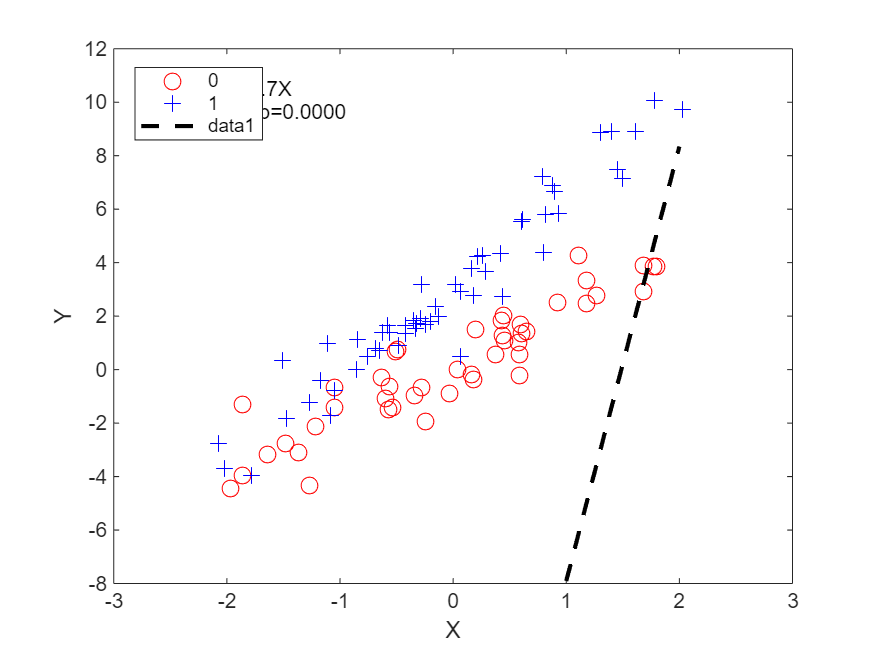

%% 生成模拟数据（示例）
rng(1); % 设置随机种子
X = randn(100,1);       % 自变量
Z = randi([0,1],100,1); % 分组变量（0/1）
Y = 2*X + 3*Z + 1.5*X.*Z + randn(100,1); % 含交互效应的因变量

%% 拟合模型
model_full = fitlm([X Z X.*Z], Y, 'VarNames', {'X','Z','XZ','Y'}); % 全模型（含交互）
model_main = fitlm([X Z], Y, 'VarNames', {'X','Z','Y'});           % 主效应模型

%% F检验比较模型
aov = anova(model_full);
% F_value = aov.F(2);
% p_value = stats.pValue(2);

%% 绘制主效应示意图
figure
gscatter(X,Y,Z,'rb','o+',8) % 按Z分组绘制散点
hold on

% 绘制总回归线（仅X主效应）
h1 = plot(model_main.Coefficients.Estimate(1) + model_main.Coefficients.Estimate(2)*[-3 3],...
         'k--','LineWidth',2);

% 添加标注
text(-2.5, max(Y), sprintf('Y=%.1f + %.1fX\nF=%.1f, p=%.4f',...
    model_main.Coefficients.Estimate(1), model_main.Coefficients.Estimate(2),...
    model_main.ModelFitVsNullModel.Fstat, model_main.ModelFitVsNullModel.Pvalue),...
    'FontSize',10);


%% 绘制交互效应示意图
figure
gscatter(X,Y,Z,'rb','o+',8) % 按Z分组绘制散点
hold on

% 分别绘制Z=0和Z=1的回归线
X_range = linspace(min(X),max(X),100)';
for z = 0:1
    plot(X_range, model_full.Coefficients.Estimate(1) + ...
         model_full.Coefficients.Estimate(2)*X_range + ...
         model_full.Coefficients.Estimate(3)*z + ...
         model_full.Coefficients.Estimate(4)*X_range*z,...
         'Color',[z 0 1-z],'LineWidth',2)
end

% 添加交互效应标注
% text(mean(X), mean(Y), sprintf('交互效应检验\nF(%d,%d)=%.2f, p=%.4f',...
%     stats.df(2), stats.dfe, F_value, p_value),...
%     'VerticalAlignment','bottom','FontSize',10);

%% 图形美化
xlabel('自变量X'), ylabel('因变量Y')
legend({'Z=0','Z=1','主效应线','Z=0回归','Z=1回归'},'Location','best')

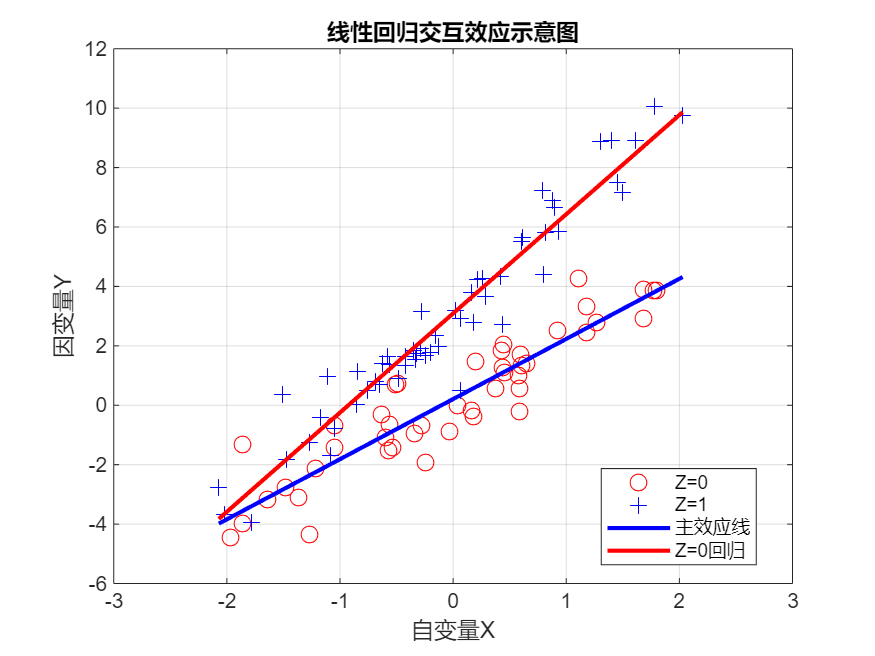

title('线性回归交互效应示意图')
grid on
hold off